# Example: COVID-2019 data for Hubei, China (22-Jan-2020-18-Mar-2020)

I am taking some data from Hubei province from John Hopkins university [1]

[1] [https://github.com/CSSEGISandData/COVID-19](https://github.com/CSSEGISandData/COVID-19)

**Important notice:**

The fitting is here more challenging than in Example 1 because the term "Confirmed patient" used in the database does not precise whether they have been quarantined or not. In a previous version of the submision (version <1.5) , the infectious cases were erroneously used instead of the quarantined cases. 

## Initialisation

The parameters are here taken as constant except the death rate and the cure rate.

clearvars;close all;clc;
load('DATA.mat','tableRecovered','tableDeaths','tableConfirmed','time')

indLocation = find(contains(tableRecovered.ProvinceState,'Hubei')==1)

indLocation = 156


Recovered = table2array(tableRecovered(indLocation,5:end));
Deaths = table2array(tableDeaths(indLocation,5:end));
Confirmed = table2array(tableConfirmed(indLocation,5:end));
% If the number of confirmed Confirmed cases is small, it is difficult to know whether
% the quarantine has been rigorously applied or not. In addition, this
% suggests that the number of infectious is much larger than the number of
% confirmed cases
Recovered(Confirmed<=10)=[];
Deaths(Confirmed<=10)=[];
time(Confirmed<=10)= [];
Confirmed(Confirmed<=10)=[];
% time = datetime(2020,02,24):1:datetime(2020,03,17);

Npop= 14e6; % population

## Fitting of the generalized SEIR model to the real data

guess = [0.06,1.2,1/5,1/40,0.1,0.05,0.1,0.02]; % my guess for the fit
E0 = 0; % Initial number of exposed cases (we do not know it, so it is set at zero)
I0 = Confirmed(1); % Initial number of infectious cases (we do not know it, so it is the number of quarantined)
Q0 = 2*Confirmed(1);
R0 = Recovered(1);
D0 = Deaths(1);

[alpha1,beta1,gamma1,delta1,Lambda1,Kappa1] = ...
    fit_SEIQRDP(Confirmed-Recovered-Deaths,Recovered,Deaths,Npop,E0,I0,time,guess);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          9      3.6952e+11                      5.25e+13
     1         18     7.01249e+10      0.0087644       7.24e+12      
     2         27     3.34926e+10       0.103762       6.38e+11      
     3         36     3.34926e+10      0.0987525       6.38e+11      
     4         45     2.84191e+10      0.0246881       2.47e+11      
     5         54     2.01958e+10      0.0246881       1.43e+11      
     6         63     1.53108e+10      0.0493762       7.08e+10      
     7         72     9.86165e+09      0.0987525        9.3e+10      
     8         81     5.03413e+09      0.0987525       9.04e+10      
     9         90     5.03413e+09       0.212323       9.04e+10      
    10         99     3.88465e+09      0.0493762        2.4e+10      
    11        108     2.89877e+09      0.0987525       5.81e+11      
    12        117     1.74638e+0

## Simulate the epidemy outbreak based on the fitted parameters

dt = 0.1; % time step
time1 = datetime(time(1)):dt:datetime(2020,04,1,0,0,0);
N = numel(time1);
t = [0:N-1].*dt;
[S,E,I,Q,R,D,P] = SEIQRDP(alpha1,beta1,gamma1,delta1,Lambda1,Kappa1,Npop,E0,I0,Q0,R0,D0,t);

## Comparison of the fitted and real data

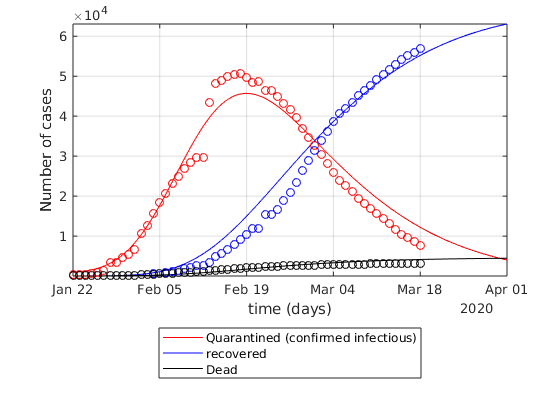

figure
semilogy(time1,Q,'r',time1,R,'b',time1,D,'k');
hold on
semilogy(time,Confirmed-Recovered-Deaths,'ro',time,Recovered,'bo',time,Deaths,'ko');
% ylim([0,1.1*Npop])
ylabel('Number of cases')
xlabel('time (days)')
% leg = {'susceptible','exposed','infectious','quarantined','recovered','Dead','insusceptible'};
leg = {'Quarantined (confirmed infectious)','recovered','Dead'};
legend(leg{:},'location','southoutside')
set(gcf,'color','w')
grid on
axis tight
% ylim([1,8e4])
set(gca,'yscale','lin')